# Optimization of PID parameters for robot control position

#### Adapted Original Version

t_max = 5;

### Open-loop response: Motor 1

% Initial data
time = 0:0.05:t_max;

% Create plant
K=13.86;
T=0.0002648;
plant = tf(K,[T 1 0]);

%figure("Name","Open-loop Step Response for system");
%step(plant,0:0.05:t_max);

### Closed-loop response: Motor 1

% Differential Evolution initial parameters
config = struct();
config.populationSize = 20;
config.maxIterations = 20;
config.F = 0.7;
config.CR = 0.5;
config.maxPIDValue = 1;% At initialization

% PID otimization
%Solutionv1_1 = Control_PID_modified(plant,config,"motor 1")
Solutionv1_1 = Control_PID(plant,config,"motor 1")

% PID parameters 
% Kp1 = Solutionv1_1.bestmem(1);
% Ki1 = Solutionv1_1.bestmem(2);
% Kd1 = Solutionv1_1.bestmem(3);

% Create the PID controller 
% Form: Kd*s + Kp + Ki/s
% C1 = tf([Kd1 Kp1 Ki1], [1 0]);
% C1 = pid(Kp1,Ki1,Kd1);

% Create the closed-loop system
% control_response1 = feedback(C1*plant, 1);

% Plot the step response
% figure("Name","PID Optimization for position control: motor 1 ");
% y = step(control_response1, time);
% plot(time, y, '-r', 'DisplayName', 'Estimated tf')
% grid on
% xlabel('Time (s)', 'FontSize', 12)
% ylabel('Position', 'FontSize', 12)
% title('Optimized Closed-loop Step Response: motor 1')
% legend('Location', 'best')

% version - original old
% Kp1 = 18.511011;
% Ki1 = 0;
% Kd1 = 0.493401;

% version - original
% bestmem: [11.8483 0.1859 0.0039] 
% error: 0.2149 
% Kp1 = 11.8483;
% Ki1 = 0.1859;
% Kd1 = 0.0039;

% Version - fixed 
% bestmem: [3.3180 0.1642 0.1163]
% error: 0.3370


### Open-loop response: Motor 2

% Create plant
K=32.8;
T=0.2307;
plant = tf(K,[T 1 0]);

% figure("Name","Open-loop Step Response for system");
% step(plant,0:0.05:t_max);

### Closed-loop response: Motor 2

% Differential Evolution initial parameters
config = struct();
config.populationSize = 20;
config.maxIterations = 30;
config.F = 1;
config.CR = 0.5;
config.maxPIDValue = 2;% At initialization

joint1_ctrl = 60;
joint2_ctrl = 140;
joint3_ctrl = 0;
joint4_ctrl = 0;
joint5_ctrl = 0;
joint6_ctrl = 0;

% PID otimization
Solutionv1_2 = Control_PID2(plant,config,": motor 2")
 
% bestmem: [6.8477 0 0.7081]
% error: 0.3904

% bestmem: [0.8422 0.5569 0.8399]
% error: 0.3911

% bestmem: [0.7898 0.1023 0.7679]
% error: 0.5418



% Solutionv1_2 = 
% bestmem: [0.5082 0.8534 0.6838]
% error: 0.4811


% config.populationSize = 20;
% config.maxIterations = 20;
% config.F = 0.7;
% config.CR = 1;
% config.maxPIDValue = 5;% At initialization
% Solutionv1_2 = 
% bestmem: [17.7028 18.4274 0.0104]
% error: 0.1964
% Funciona

% config.maxPIDValue = 3;% At initialization
% prueba 1
% Solutionv1_2 = 
% bestmem: [12.3782 0 1.2419]
% error: 0.2714

% config.maxPIDValue = 2.5;% At initialization
% Solutionv1_2 = 
% bestmem: [11.8651 0.0902 1.5077]
% error: 0.2760


% config.maxPIDValue = 2;% At initialization y modelo_opt
% Kp 6.8546
% Ki 0.002
% Kd 2.3968
% error = 0.3318

% config.maxPIDValue = 2;% At initialization y modelo_orig
% 8min
% bestmem: [12.5526 0 1.0084]
% error: 0.2689

% config.maxPIDValue = 2;% At initialization y modelo_orig2
% 10min 
% Solutionv1_2 = 
% bestmem: [9.1258 0.0598 2.2645]
% error: 0.3014
% Funciona se parece al de kP 6


% config.populationSize = 20;
% config.maxIterations = 30;
% config.F = 1;
% config.CR = 0.5;
% config.maxPIDValue = 2;% At initialization
% Solutionv1_2 = 
% bestmem: [70.7197 28.9111 3.6063]
% error: 0.1059



% PID parameters 
% Kp2 = Solutionv1_2.bestmem(1);
% Ki2 = Solutionv1_2.bestmem(2);
% Kd2 = Solutionv1_2.bestmem(3);
% 
% % Create the PID controller 
% % Form: Kd*s + Kp + Ki/s
% % C1 = tf([Kd1 Kp1 Ki1], [1 0]);
% C2 = pid(Kp2,Ki2,Kd2);
% 
% % Create the closed-loop system
% control_response2 = feedback(C2*plant, 1);

% % Plot the step response
% figure("Name","PID Optimization for position control: motor 2 ");
% y = step(control_response2, time);
% plot(time, y, '-r', 'DisplayName', 'Estimated tf')
% grid on
% xlabel('Time (s)', 'FontSize', 12)
% ylabel('Position', 'FontSize', 12)
% title('Optimized Closed-loop Step Response: motor 2')
% legend('Location', 'best')

% figure('Name', 'Convergence History for PID optimization');
% plot(1:20, Solutionv1_1.CONV.MIN, 'b-', 'LineWidth', 2);
% hold on;
% plot(1:20, Solutionv1_1.CONV.MAX, 'r--', 'LineWidth', 2);
% plot(1:20, Solutionv1_1.CONV.GLOBAL, 'g:', 'LineWidth', 2);
% xlabel('Iteration', 'FontSize', 12);
% ylabel('Cost', 'FontSize', 12);
% title('Convergence History: motor 2');
% legend('Best', 'Worst', 'Global', 'Location', 'NorthEast');
% grid on;
% hold off;

% Kp3 = 3;
% Ki3 = 3;
% Kd3 = 3;
% 
% Kp4 = 3;
% Ki4 = 3;
% Kd4 = 3;
% 
% Kp5 = 3;
% Ki5 = 3;
% Kd5 = 3;
% 
% Kp6 = 3;
% Ki6 = 3;
% Kd6 = 3;


### Open-loop response: Motor 3

% Create plant
K=29.85;
T=0.001451;
plant = tf(K,[T 1 0]);

% figure("Name","Open-loop Step Response for system");
% step(plant,0:0.05:t_max);

### Closed-loop response: Motor 3

Iteration: 5
Best Error: 0.3836 | Worst Error: 0.4829 | Global Error: 8.5818
PID Parameters - Kp: 7.0972 | Ki: 3.5796 | Kd: 0.0000

Iteration: 10
Best Error: 0.3405 | Worst Error: 0.4039 | Global Error: 7.5927
PID Parameters - Kp: 11.2559 | Ki: 7.8733 | Kd: 0.8052

Iteration: 15
Best Error: 0.3121 | Worst Error: 0.3555 | Global Error: 6.7148
PID Parameters - Kp: 10.3105 | Ki: 15.3578 | Kd: 0.0000

Iteration: 20
Best Error: 0.2991 | Worst Error: 0.3276 | Global Error: 6.2504
PID Parameters - Kp: 10.3105 | Ki: 25.0217 | Kd: 0.8880



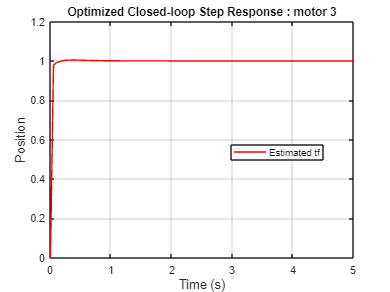

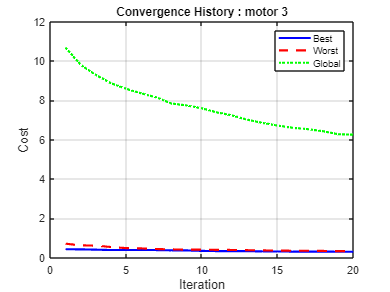

Solutionv1_2 = struct with fields:
       bestmem: [10.3105 25.0217 0.8880]
         error: 0.2991
    population: [20×4 double]
          CONV: [1×1 struct]
             M: [1×1 tf]

% Differential Evolution initial parameters
config = struct();
config.populationSize = 20;
config.maxIterations = 20;
config.F = 0.7;
config.CR = 0.5;
config.maxPIDValue = 5;% At initialization

joint1_ctrl = 60;
joint2_ctrl = 140;
joint3_ctrl = 70;
joint4_ctrl = 0;
joint5_ctrl = 0;
joint6_ctrl = 0;

% PID otimization
Solutionv1_2 = Control_PID2(plant,config,": motor 3")


% config = struct();
% config.populationSize = 20;
% config.maxIterations = 20;
% config.F = 0.7;
% config.CR = 0.5;
% config.maxPIDValue = 5;% At initialization
% Solutionv1_2 = 
% bestmem: [15.6143 72.1112 0.0851]
% error: 0.2350

% Iteration: 5
% Best Error: 0.3445 | Worst Error: 0.4558 | Global Error: 8.2098
% PID Parameters - Kp: 6.8227 | Ki: 9.2459 | Kd: 0.3407
% 
% Iteration: 10
% Best Error: 0.3219 | Worst Error: 0.3886 | Global Error: 6.9475
% PID Parameters - Kp: 7.5710 | Ki: 14.1220 | Kd: 0.0000
% 
% Iteration: 15
% Best Error: 0.2715 | Worst Error: 0.3271 | Global Error: 6.0359
% PID Parameters - Kp: 11.6785 | Ki: 37.8982 | Kd: 0.1216
% 
% Iteration: 20
% Best Error: 0.2350 | Worst Error: 0.2985 | Global Error: 5.2691
% PID Parameters - Kp: 15.6143 | Ki: 72.1112 | Kd: 0.0851

%-----
% Solutionv1_2 = 
%        bestmem: [10.3105 25.0217 0.8880]
%          error: 0.2991